% Q1 - load dataset
loaded_data = load('Exercise_8_data.mat');
data = loaded_data.data;
event = loaded_data.event;

num_records = numel(data);

% Check for missing/damaged records
damaged_idx = [];
for i = 1:num_records
    x = data(i).x;
    t = data(i).time;
    if any(isnan(x)) || any(isnan(t)) || length(x) ~= length(t)
        damaged_idx(end+1) = i;
    end
end
fprintf('Damaged record(s): %s\n', mat2str(damaged_idx));

Damaged record(s): 57


fprintf('Record %d - NaNs in x: %d, NaNs in time: %d\n', ...
    damaged_idx(1), sum(isnan(data(damaged_idx(1)).x)), sum(isnan(data(damaged_idx(1)).time)));

Record 57 - NaNs in x: 0, NaNs in time: 10001



% Dynamic range across records
mins = zeros(num_records, 1);
maxs = zeros(num_records, 1);
spans = zeros(num_records, 1);

for i = 1:num_records
    mins(i) = min(data(i).x);
    maxs(i) = max(data(i).x);
    spans(i) = maxs(i) - mins(i);
end

fprintf('Dynamic range (span) across records: min = %.2f, max = %.2f, mean = %.2f\n', ...
    min(spans), max(spans), mean(spans));

Dynamic range (span) across records: min = 97.39, max = 279.51, mean = 161.08



% Sampling interval check (skip the damaged record)
valid_idx = setdiff(1:num_records, damaged_idx);
dt_mean = zeros(length(valid_idx), 1);
dt_std = zeros(length(valid_idx), 1);

for k = 1:length(valid_idx)
    dt = diff(data(valid_idx(k)).time);
    dt_mean(k) = mean(dt);
    dt_std(k) = std(dt);
end

fprintf('Mean sampling interval range: [%.2f, %.2f]\n', min(dt_mean), max(dt_mean));

Mean sampling interval range: [10.00, 10.00]


fprintf('Sampling interval std range: [%.2f, %.2f]\n', min(dt_std), max(dt_std));

Sampling interval std range: [2.19, 3.01]


fprintf('Avg coefficient of variation: %.1f%%\n', mean(dt_std ./ dt_mean) * 100);

Avg coefficient of variation: 26.2%



% Quantization check - repeated values relative to record length
dup_frac = zeros(num_records, 1);
for i = 1:num_records
    x = data(i).x;
    dup_frac(i) = 1 - length(unique(x)) / length(x);
end
fprintf('Max duplicate-value fraction across records: %.4f\n', max(dup_frac));

Max duplicate-value fraction across records: 0.0000


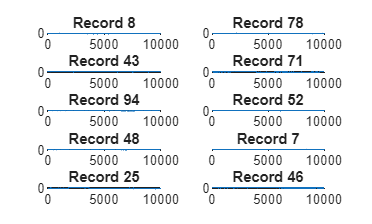


% Plot 10 randomly selected records
rng(7);
sample_idx = randperm(num_records, 10);

figure;
for k = 1:10
    subplot(5, 2, k);
    plot(data(sample_idx(k)).x);
    title(sprintf('Record %d', sample_idx(k)));
end

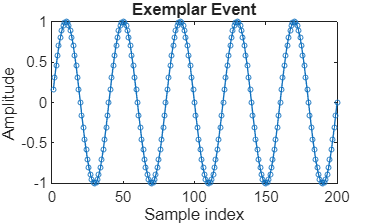


% Plot the event
figure;
plot(event, '-o', 'MarkerSize', 3);
title('Exemplar Event');
xlabel('Sample index'); ylabel('Amplitude');

Record 57 contains errorneous data, its time vector is entirely NaN even though the measurement data itself is fine, suggesting a timestamp logging fault rather than a sensor fault. 

Dynamic range varies a fair bit record to record (span roughly 100–280), so normalization should probably be done per-record rather than globally. 

Every valid record shows a mean sampling interval of about 10, but with a standard deviation around 25–30% of that, this is genuinely stochastic sampling, consistently across the whole dataset, not just a few noisy records. No duplicate values turn up in any record, so there's no evidence of coarse quantization. 

The 10 plotted records are visibly noisy with wandering baselines, occasional spikes, and a few sharp level shifts partway through. The event itself is a clean, smooth, ~5-cycle sinusoidal burst with no noise, easy to recognize in isolation, but given how noisy and non-stationary the actual records are, finding it reliably embedded in real data is a different problem entirely.

% Q2 - locate examples of the event within the data records
L = length(event);
event_z = (event - mean(event)) / std(event);

best_corr = zeros(num_records, 1);
best_pos = zeros(num_records, 1);

for i = 1:num_records
    x = data(i).x;
    n = length(x);
    top_c = -2;
    top_p = 1;
    for start = 1:5:(n - L)
        w = x(start:start+L-1);
        w_std = std(w);
        if w_std < 1e-9
            continue
        end
        w_z = (w - mean(w)) / w_std;
        c = sum(w_z .* event_z) / L;
        if c > top_c
            top_c = c;
            top_p = start;
        end
    end
    best_corr(i) = top_c;
    best_pos(i) = top_p;
end

% Grab the 10 strongest matches
[sorted_corr, sort_idx] = sort(best_corr, 'descend');
top10_records = sort_idx(1:10);
top10_pos = best_pos(top10_records);

fprintf('Top 10 correlation scores:\n');

Top 10 correlation scores:


disp([top10_records, top10_pos, sorted_corr(1:10)])

   1.0e+03 *

    0.0650    6.8710    0.0007
    0.0080    3.9560    0.0007
    0.0660    8.8560    0.0007
    0.0530    1.9810    0.0007
    0.0230    8.4360    0.0007
    0.0640    2.1060    0.0007
    0.0770    0.7260    0.0007
    0.0980    2.8710    0.0006
    0.0900    9.7610    0.0006
    0.0340    3.4010    0.0006



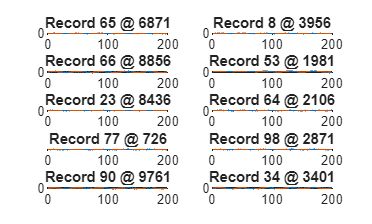


% Plot the 10 found examples against the event template
figure;
for k = 1:10
    subplot(5, 2, k);
    rec = top10_records(k);
    pos = top10_pos(k);
    seg = data(rec).x(pos:pos+L-1);
    seg_z = (seg - mean(seg)) / std(seg);
    plot(seg_z); hold on;
    plot(event, '--');
    title(sprintf('Record %d @ %d', rec, pos));
    hold off;
end

The strongest matches only reach correlation coefficients around 0.63–0.67 rather than close to 1.0, which tells us right away that no occurrence of the event in the actual data is a clean, unaltered copy of the exemplar. Each occurrence is embedded in noise, sits at a different amplitude/scale depending on that record's own dynamic range, and shows small timing shifts consistent with the stochastic sampling we found in Q1. 

So the 10 examples are all recognizably the same underlying sinusoidal burst shape, but no two are identical, there's real occurrence-to-occurrence variation in noise level, amplitude, and slight timing/phase.

This is exactly why a neural network by itself isn't a good solution here. We only have ~100 records total, giving very few labeled true-positive examples to train on, nowhere near enough for a network to learn robust invariance to amplitude scaling, timing jitter, and noise on its own. A plain feedforward network has no built-in translation or time-warp invariance, so it would need to see the event at every possible position/scale/noise condition during training to generalize, which this dataset can't provide. A correlation/matched-filter approach, by contrast, directly exploits the fact that we already know the exact shape we're looking for and needs no training data at all; it's simpler, more data-efficient, and more interpretable for this specific problem.